# Lattice Modulation, Scan Force

## Set atom and magnetic field

% atom
atom = Alkali("Lithium7");

% B field
bList = num2cell(linspace(1.235e-2,1.255e-2,100));
niB = 543.6e-4; %non-interacting feshbach field
bField = cellfun(@(x) MagneticField(...
    bias = [0;0;niB],...
    gradient = [0,0,0;0,0,0;0,x,0]),bList,'UniformOutput',false);

## Set benchmark simulation

% set laser
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 0.6, ...
    waist = 110e-6 ...
    );
laser = {laser};

% set optical lattice
ol = OpticalLattice(atom,laser{1});
ol.DepthSpec = 7.735 * ol.RecoilEnergy;
ol.updateIntensity;
kL = ol.Laser.AngularWavenumber;
laser = {ol.Laser};


% set modulation
% pulse1 = TrapezoidalSinePulse( ...
%     amplitude=0.035 * 4 * 2, ...
%     duration=5e-3, ...
%     frequency=121e3, ...
%     startTime=0,riseTime=1e-4,fallTime=1e-4);
% pulse2 = TrapezoidalSinePulse( ...
%     amplitude=0.035 * 2, ...
%     duration=8e-3, ...
%     frequency=143.2231e3, ...
%     startTime=5e-3,riseTime=1e-4,fallTime=1e-4);
% latticeMod = WaveformList("LatticeMod");
% latticeMod.WaveformOrigin = {pulse1,pulse2};
% latticeMod.ConcatMethod = "Simultaneous";

load WaveformLibrary.mat
latticeMod = WaveformLibrary(18);
latticeMod.WaveformOrigin{1}.Amplitude = 0.24;
latticeMod.WaveformOrigin{1}.Frequency = 110e3;
latticeMod.WaveformOrigin{1}.Duration = 5.3e-3;
latticeMod.WaveformOrigin{2}.Frequency = 95.563e3;
latticeMod.WaveformOrigin{2}.AmplitudeModulation.WaveformOrigin{1}.Duration = 0.001e-3;
latticeMod.WaveformOrigin{2}.AmplitudeModulation.WaveformOrigin{2}.Duration = 3.106e-3;
latticeMod.WaveformOrigin{2}.AmplitudeModulation.WaveformOrigin{3}.Duration = 2 * 2.194e-3;
latticeMod.WaveformOrigin{2}.AmplitudeModulation.WaveformOrigin{4}.Duration = 3.106e-3;
latticeMod.WaveformOrigin{2}.AmplitudeModulation.WaveformOrigin{4}.Amplitude = 0.023 * 4;
latticeMod.WaveformOrigin{2}.AmplitudeModulation.WaveformOrigin{2}.Amplitude = 0.023 * 4;
latticeMod.WaveformOrigin{2}.StartTime = 0;

% latticeMod.SamplingRate = 10e6;
latticeMod = {latticeMod};

ic = InitialCondition("SeSim1D");
se2 = LatticeSeSim1D("Test", ...
    laser = laser,...
    magneticField = bField,...
    latticeModulation = latticeMod,...
    timeStep=1e-7,...
    totalTime=16.4e-3,...
    spaceRange = 1000e-06,...
    spaceStep = 1e-8,initialCondition = ic);

Constructing the object.
Setting up folders.
Creating a database entry.
Updating the object file.



% initial condition
x = se2.SimRun(1).SpaceList;
x = x.';

momentumWidth = 0.1 * kL;
sigma = 5e-6;
kL = ol.Laser.AngularWavenumber;
qIni = -kL;
% qmin = - kL;
% qmax =  kL;
% qList = linspace(qmin,qmax,5000);
% qList = qList(1:end-1);
% [~,qIdx] = min(abs(qList - qIni));
% [E,~,~,ck] = ol.computeBand1D(qList,0,x);
% % ck = ol.BlochStateFourier;
% vn = ck(:,2,qIdx).';
% vn = repmat(vn,numel(x),1);
% nmax = max(2 * 2+49,101);
% k = (1-nmax:2:nmax-1) * kL;
% k = repmat(k,numel(x),1);
% 
% temp = vn.* exp(1i*(k+qList(qIdx)).* x);
% phi = sum(temp,2);
[~,~,phi] = ol.computeBand1D(qIni,0,x);

psi = exp(-(x).^2 / 4 / sigma^2) .* phi;
ic.WaveFunction = psi;
for ii = 1:numel(se2.SimRun)
    se2.SimRun(ii).InitialCondition.WaveFunction = psi;
end

se2.start

Updating the object file.
Python Error: ValueError: There is no data available on HFS structure of 2 P 1/2 state
> In parallel.internal.pool.optionallyDeserialize (line 7)
In parallel.internal.parfor.cppRemoteParallelFunction (

## Analysis: animation

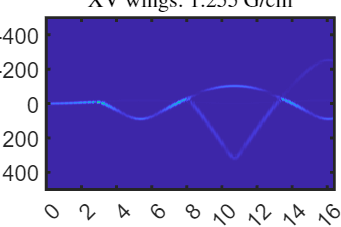

trialNumber = 42;
startDelay=.5;
midDelay=.1;
endDelay=.5;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
filename = fullfile(obj.DataAnalysisPath,"AI_Force_Scan.gif");
nSpace = obj.SimRun(1).NSpaceStep;
nRun = numel(obj.SimRun);
psiList = zeros(nRun,nSpace);
psi1 = obj.SimRun(1).readRun("WaveFunction");
psi1 = psi1(1,:);
n1 = abs(psi1).^2;
nLim = max(n1);
for ii = 1:nRun
    psiList(ii,:) = obj.SimRun(ii).readRun("FinalWaveFunction");
    obj.SimRun(ii).showSpaceTime;
    fig = gcf;
    imgAxes = gca;
    imgAxes.CLim = [0,nLim];

    % Update title
    imgAxes.Title.String = "XV wings: $" + num2str(norm(bField{ii}.GradientLu)) + "~\mathrm{G/cm}$";
    imgAxes.Title.Interpreter = "latex";
    render

    % Save as gif
    frame = getframe(fig);
    im = frame2im(frame);
    [A,map] = rgb2ind(im,256);
    if ii == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',startDelay);
    else
        if ii==nRun
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',endDelay);
        else
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',midDelay);
        end
    end
end

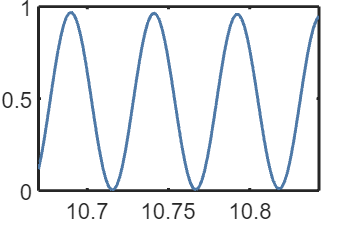

obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
x = obj.SimRun(1).SpaceList;
bandPop = ol.computeBandPopulation1D(psiList,int32(2),x);
% bListGauss = cell2mat(bList) * 1e2;

mp = MagneticPotential(atom,bField{1});
stateIdx = mp.StateIndex;
stateList = atom.(mp.Manifold).StateList;
mJ = stateList.MJ(stateIdx);
gJ = stateList.gJ(stateIdx);
mI = stateList.MI(stateIdx);
gI = stateList.gI(stateIdx);
muB = Constants.SI("muB");
h = Constants.SI("hbar") * 2 * pi;
hbar = Constants.SI("hbar");
prefactor = (mJ * gJ + mI * gI) * muB / h;
FList0 = abs(h * prefactor * cell2mat(bList));
g = 9.81;
M = atom.mass;
a = laser{1}.Wavelength/2;
% a = obj.Laser{1}.Wavelength/2;
h = Constants.SI('hbar')*2*pi;
fB = FList0*a/h;
%%
fig = figure;
plot(1./fB * 1e3,bandPop)
xlabel("$T_{\mathrm{B}}$ [ms]")
ylabel("$D$ Band Fraction")
% legend("s","p","d")
render
saveas(gcf,fullfile(obj.DataAnalysisPath,"AI_Force_Scan"),"png")

saveas(gcf,fullfile(obj.DataAnalysisPath,"AI_Force_Scan"),"fig")
